# AAE 340 HW 12 MATLAB CODE 

## Problem 1

## Author: Tomoki Koike 

clear all;
close all;
clc;

% Defining the constants
% Mass [kg]
m = 2000;  
% PMOI [kg-m^2]
Ix = 3012; 
Iy = 2761;
Iz = 4627;
% Body fixed forces [N]
fx = 0;
fy = 0;
fz = 400;
% Torque [N-m]
Mx = 0;
My = -8;
Mz = 0;

% Defining the ICs for the ode45
% Angular velocity [rad/s]
wx0 = 0;
wy0 = 0;
wz0 = 10*2*pi/60;
% Angles [rad]
phi0 = 0;
theta0 = -pi/2;
psi0 = 0;
% Velocities [m/s]
Vx0 = 0;
Vy0 = 0;
Vz0 = 0;
% Initial Conditions 
ICs = [wx0, wy0, wz0, phi0, theta0, psi0, Vx0, Vy0, Vz0];

% Solving the ode45
tspan = 0:0.001:60;
options = odeset('RelTol',1e-12, 'AbsTol',1e-12);
[t, Xs] = ode45(@(t, x) EOMKinematicEqn(t, x, Ix, Iy, Iz,...
    Mx, My, Mz, fz, m), tspan, ICs, options);
% Setting variables to the obtained results
wx = Xs(:,1);
wy = Xs(:,2);
wz = Xs(:,3);
phi = Xs(:,4);
theta = Xs(:,5);
psi = Xs(:,6);
Vx = Xs(:,7);
Vy = Xs(:,8);
Vz = Xs(:,9);


## <1a>

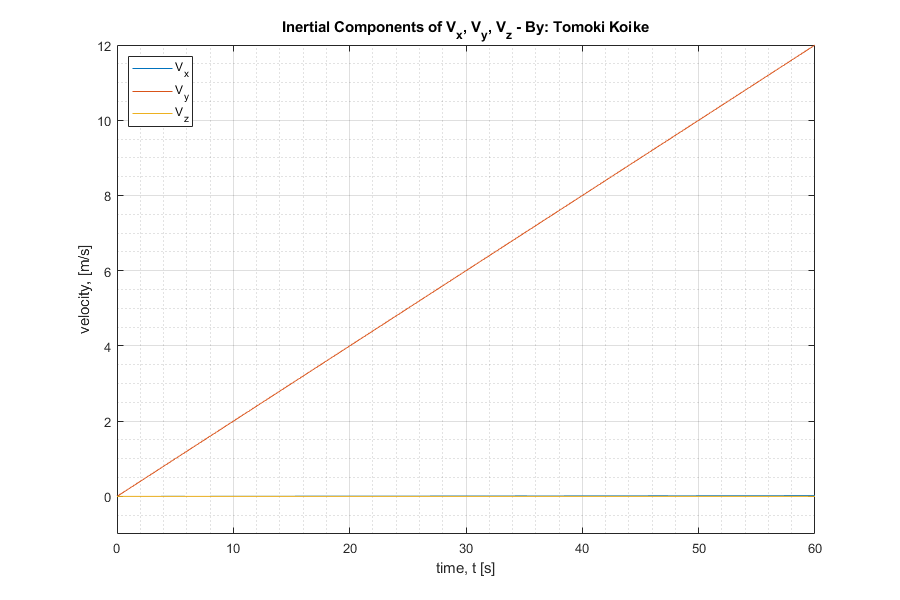

% Plotting
figure('Renderer',"painters", "Position",[10 10 900 600]);
plot(t, Vx)
title({'Inertial Components of V_x, V_y, V_z - By: Tomoki Koike'})
xlabel('time, t [s]')
ylabel('velocity, [m/s]')
hold on
plot(t, Vy)
plot(t, Vz)
hold off
grid on
grid minor
box on
legend('V_x', 'V_y', 'V_z', 'Location', 'northwest')
ylim([-1 12])

## <1b>

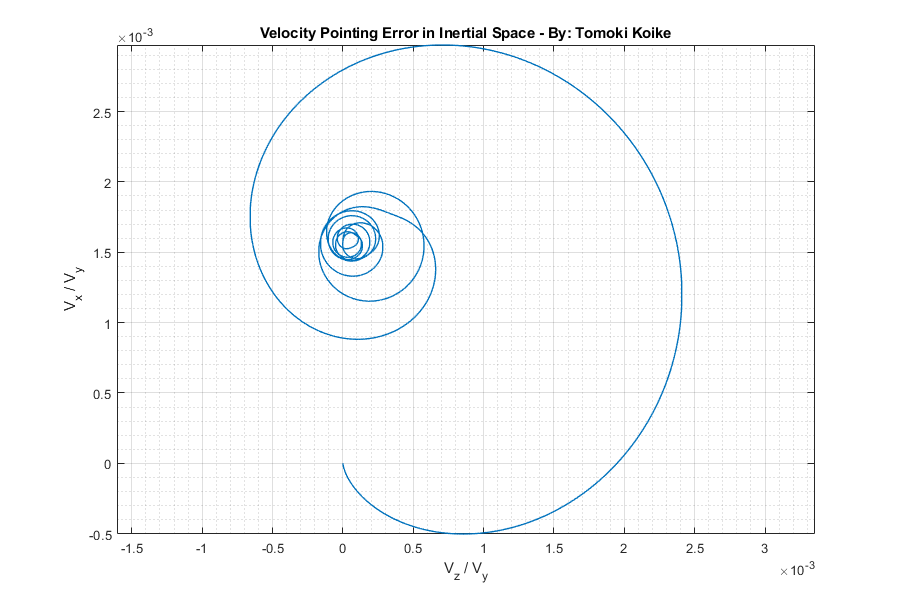

% Plotting
zyRat = Vz./Vy;
xyRat = Vx./Vy;
figure('Renderer',"painters", "Position",[10 10 900 600]);
plot(zyRat, xyRat, "LineWidth", 1)
title({'Velocity Pointing Error in Inertial Space - By: Tomoki Koike'})
xlabel('V_z / V_y')
ylabel('V_x / V_y')
grid on
grid minor
box on
axis equal

## Analysis

This Vz/Vy vs Vx/Vy plot looks identical to the plot of figure 6a. on p443 of paper by Prof. Longuski, Kia, and Breckenridge. 

## <1c>

rho0 = xyRat(end) - xyRat(2);
rho0 = vpa(rho0, 7);
disp(rho0);

$$0.001579258$$

## Functions

function dxdt = EOMKinematicEqn(t, x, Ix, Iy, Iz, Mx, My, Mz, fz, m)
    % Space State System
    wx = x(1);
    wy = x(2);
    wz = x(3);
    phi = x(4);
    theta = x(5);
    psi = x(6);
    Vx = x(7);
    Vy = x(8);
    Vz = x(9);
    
    dxdt(1) = (Mx - (Iz - Iy)*wy*wz)/Ix;
    dxdt(2) = (My - (Ix - Iz)*wz*wx)/Iy;
    dxdt(3) = (Mz - (Iy - Ix)*wx*wy)/Iz;
    dxdt(4) = (sin(psi)*wx + cos(psi)*wy)/sin(theta);
    dxdt(5) = cos(psi)*wx - sin(psi)*wy;
    dxdt(6) = wz - cos(theta)/sin(theta)*(sin(psi)*wx + cos(psi)*wy);
    dxdt(7) = sin(theta)*sin(phi)*fz/m;
    dxdt(8) = -sin(theta)*cos(phi)*fz/m;
    dxdt(9) = cos(theta)*fz/m;
    dxdt = dxdt';
end